# ORR - lab 1 - Gentle introduction to optimization in Matlab

## Polynomial Regression

In this task, you will learn how to fit polynomial models to a given dataset. Specifically, given $N$ data points $(x_k, y_k)$, you will find coeficients $\alpha_i$ of a polynomial


$$
   p(x)= \sum_{i=0}^m \alpha_i x^i
$$


minimizing quadratic error $\sum_{k=1}^N(y_k-p(x_k))^2$.

This optimization problem is an instance of the famous **Least Squares** and it is so commonly solved that there is actually a built-in Matlab function for it (see *doc polyfit*). Nevertheless, in order to master optimization tools available in Matlab, you will write your own code solving this problem. If you want to know more about Least Squares, check out the freely available book *Introduction to Applied Linear Algebra* by Stephen Boyd. Even if you are not interested in least squares, I encourage you to at least skim throught the book as this book truly is a nice gentle introduction to the basic of appled linear algebra.

## Example 1: Line fitting

The simplest class of polynomials (except constants) are lines or linear polynomials, so let us begin with this class. A linear polynomial can be written as $p(x) = \alpha_1 x + \alpha_0$, so the goal here is to find coefficients $\alpha_1$ and $\alpha_0$ minimizing the quadratic error $\sum_{k=1}^N(y_k - p(x_k))^2$.

At first, load and visualize the data to be fitted.

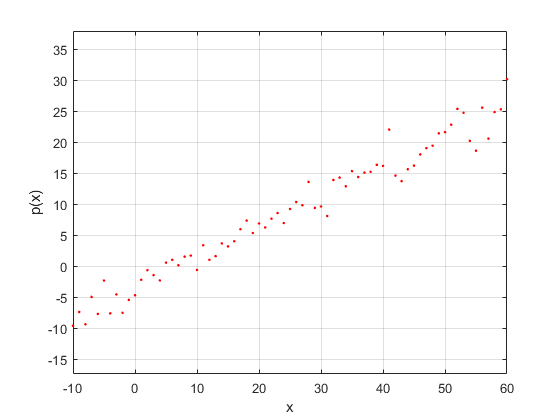

load('data_linPol.mat')
figure(1)
plot(x, y, 'r.')
xlabel('x')
ylabel('p(x)')
axis equal
grid on

Let us express the quadratic error $\sum_{k=1}^N(y_k-p(x_k))^2$ in a vector form. The vector $[p(x_1), \dots, p(x_N)]^T$ can be expressed as


$$
\left[
\begin{array}{c}
       p(x_1) \\
       \vdots \\
       p(x_N) \\ 
    \end{array}
\right]
=
\left[
\begin{array}{cc}
       1 & x_1 \\
       \vdots & \vdots \\ 
       1 & x_N \\
    \end{array}
\right]
\left[
\begin{array}{c}
       \alpha_0 \\
       \alpha_1 
    \end{array}
\right],
$$


where the matrix


$$
\left[
\begin{array}{cc}
       1 & x_1 \\
       \vdots & \vdots \\ 
       1 & x_N \\
    \end{array}
\right],
$$


is called a *Vandermonde matrix* and, for notational convenience, we will denote it by $\mathbf{A}$. Let us generate this matrix for our dataset:

A = [ones(numel(x), 1) x];

The problem of line fitting can be now reformualted to the problem:


$$
  \min_{\alpha_0, \alpha_1} \Vert\mathbf{A}\alpha -\mathbf{y} \Vert_2
$$


Next, we show several ways how to solve this problem.

**CVX**

Let us begin with *CVX* which is a Matlab-based framework for modeling and solving of convex optimization problems. For more details, visit [cvxr.com](http://cvxr.com/). CVX is freely available and it is interfaced not only to Matlab but also to Python ([link](https://cvxopt.org/)) and Julia ([link](https://github.com/JuliaOpt/Convex.jl)). If you do not have CVX installed on your PC, install it by following the official [installation instructions](http://cvxr.com/cvx/doc/install.html).

Our optimization problem of line fitting can be solved by CVX by the following piece of code:

cvx_begin
    variable alph(2)
    minimize( norm(A*alph - y) )
cvx_end

 
Calling SDPT3 4.0: 72 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of socp   var  = 72,   num. of socp blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.7e+00|2.2e+00|2.3e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|4.4e-05|7.0e-04|2.1e+02|-1.916470e+00 -2.136085e+02| 0:0:00| chol  1  1 
 2|1.000|0.928|6.1e-08|1.2e-04|1.5e+01|-4.284175e+00 -1.941405e+01| 0:0:00| chol  1  1 
 3|0.922|1.000|1.5e-08|7.0e-06|9.8e-01|-1.569658e+01 -1.667707e+

fprintf('Alpha found by CVX: %s\n', mat2str(alph, 3))

Alpha found by CVX: [-3.44;0.489]


**Optimization Toolbox**

Optimization toolbox provides several functions solving various optimization problems. To name a few, *fminunc()* is designed for solving nonlinear unconstrained optimization problems, *fmincon()* for nonlinear constrained optimization problems, *quadprog()* for quadratic problems and *linprog()* for linear optimization problems. Oh, by the way, there is also a speciliazed function for constrained linear least squares called *lsqlin()*. For details call *doc optim* in Matlab.

Let us the most general function and solve our optimization problem by *fminunc()*. The fminunc requires a function handler to the objective function as the first parameter and an intial guess as the second parameter. So let us define the objective function as an anonymous function, choose an arbitrary initial guess and call *fminunc()*:

obj_fun = @(a) norm(A*a - y);
alph0 = [0;0];
alph_ot = fminunc(obj_fun, alph0);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


fprintf('Alpha found by Optimization Toolbox: %s\n', mat2str(alph_ot, 3))

Alpha found by Optimization Toolbox: [-3.44;0.489]


**Other options** Just for the record, the same optimization problem can be also solved by the following commands:

alph_matlab = flip(polyfit(x, y, 1))';
alph_matlab2 = A\y;

Finally, let us have a look how the line fits to the data.

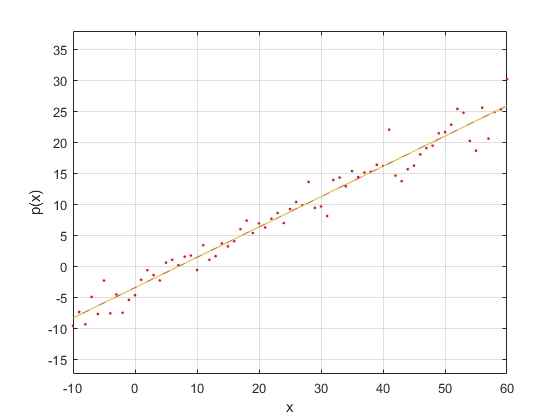

figure(1)
plot(x, y, 'r.', x, A*alph, '-', x, A*alph_ot, '--')
xlabel('x')
ylabel('p(x)')
axis equal
grid on

## Exercise 1: Cubic polynomial fitting

Follow one of the approaches shown in Example 1 and fit a cubic polynomial to the following dataset.

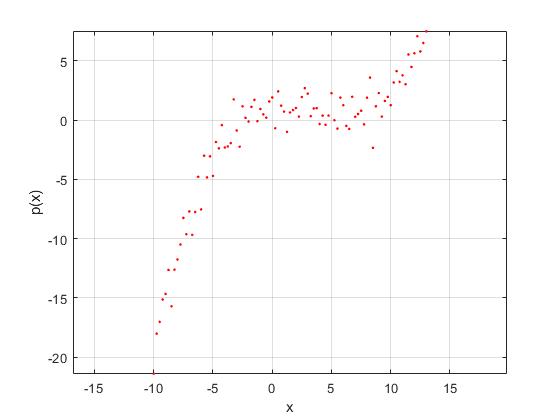

load data_quadPol
figure(2)
plot(x, y, 'r.')
xlabel('x')
ylabel('p(x)')
axis equal
grid on

% Your code goes here

## (Optional) Exercise 2: Fitting higher-order polynomials

Along the same lines, fit a higher-order polynomial to the dataset stored in `data_higherOrderPol.mat`. This time, however, the order of the polynomial is not specified beforehand and you have to find the best model by yourself.

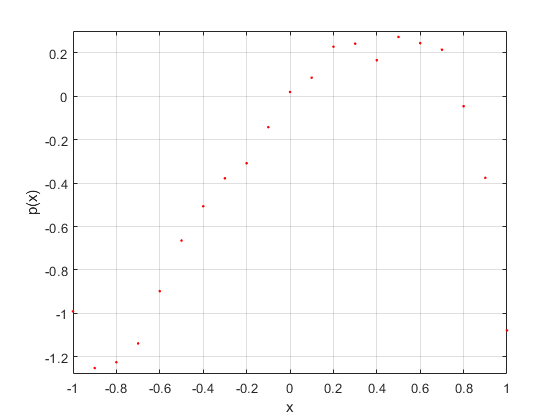

load('data_higherOrderPol.mat')
figure(2)
plot(x, y, 'r.')
xlabel('x')
ylabel('p(x)')
axis equal
grid on

% Your code goes here

## Exercise 3: Optimal Street Lamp Control

You have a set of $N$ uneavenly spreaded street lamps illuminating an area dividied to $m$ regions. Let $l_i$ denote lighting level in region $i$, so the $m$-vector $\mathit{\mathbf{l}}$ gives the illumination levels across all regions. We let $p_i$ denote the power at which lamp $i$ operates, so that the $N$-vector $\mathit{\mathbf{p}}$ is the set of lamp powers. The vector of lighting levels $\mathit{\mathbf{l}}$ is given by a linear transformation of lamp powers $\mathit{\mathbf{p}}$, that is $\mathit{\mathbf{l}}=\textrm{Ap}$.

The following code initializes the problem and shows the lighting levels for the case when all lamps are powered to the maximum.

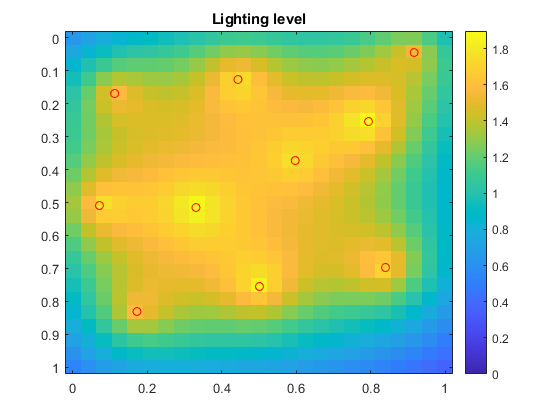

% Positions of the lamps
lamp_pos = [0.112375192012289 0.168974732750243;0.443596390168971 0.126457725947522;0.7940188172043 0.254008746355685;0.597206221198158 0.372448979591837;0.839621735791092 0.697400388726921;0.501200076804917 0.755102040816325;0.330789170506913 0.515184645286688;0.172379032258065 0.831025267249758;0.0715725806451613 0.509110787172013;0.916426651305683 0.0444606413994171];
% Lamp intensity
lamp_intesity = [1;1;1;0.5;1.25;1;0.7;1;1;1];

n = 25;                % Grid size
m = n*n;               % Number of regions
N = length(lamp_pos);  % Number of lamps

% Compute matrix A
A = zeros(n, n, N);
xv = linspace(0,1,n);
yv = linspace(0,1,n);
[xg, yg] = meshgrid(xv, yv);
for k=1:N
    dist_mat = sqrt((xg-lamp_pos(k,1)).^2 + (yg-lamp_pos(k,2)).^2);
    A(:,:,k) = lamp_intesity(k)*1./exp(5*dist_mat);
end
A = reshape(A, m, N);

% Show the illumination levels for the case when the lamps are set to the
% maximum power
max_l = A*ones(N,1);
imagesc(xv, yv, reshape(max_l, n, n))
caxis([0 max(max_l)])
colorbar
hold on
plot(lamp_pos(:,1), lamp_pos(:,2), 'ro')
hold off
title('Lighting level')

Your goal is to optimize lamp powers $\mathit{\mathbf{p}}$ so that the lighting levels in all regions are close to 1, while you cannot exceed the maximum lamp power 1 and also you have to respect the fact that the lamp power must be positive. Mathematically speaking, vector $\mathit{\mathbf{p}}$ must satisfy the following contraint: $0\le p_i \le 1$.

% Your code goes here
ldes = ones(m,1);
cvx_begin
    variable p(N)
    minimize( norm(A*p - ldes))
    subject to
      p >= 0;
      p <= 1;
      cvx_end
      lres = reshape(A*p, n, n);

figure(2)
surf(xv, yv, lres)
caxis([0 2])
colorbar
hold on
plot(lamp_pos(:,1), lamp_pos(:,2), 'ro')
hold off

## (Optional) Exercise 4:Optimal Pool Design

Imagine you face the problem of building the largest possible pool in terms of volume under the constraint that you have tiles only to cover 50 m^2. * What is the optimal heigth, width and length of the pool? * What if you are affraid of deep water and require the pool not to be deeper than 1.5 m? Incorporate this constraint into to the optimization problem.

*Hint: This optimization problem actually falls into the category of *[Geometric Programming (GP)](https://en.wikipedia.org/wiki/Geometric_programming) *which is known for the fact that GP problems are usually non-convex but can be made convex by means of change of variables. Luckily, CVX do this for you automatically when you use it in the *[GP mode](http://cvxr.com/cvx/doc/gp.html)*.*

% Your code goes here
x = fmincon(@(x) -x(1)*x(2)*x(3), [5;5;5], ...
    [], [], [], [], [0;0;0], ...
    [Inf;Inf;Inf], @(x) deal([x(1)*x(2) + 2*(x(3)*x(1) + x(3)*x(2)) - 50], []))
x = fmincon(@(x) -x(1)*x(2)*x(3), [5;5;5], ...
    [], [], [], [], [0;0;0], ...
    [Inf;Inf;Inf], @(x) deal([x(1)*x(2) + 2*(x(3)*x(1) + x(3)*x(2)) - 50; x(3)-1.5], []))
% without the height constraint
cvx_begin gp quiet
    variables w h l
    maximize( w*h*l )
    subject to
        w*l + 2*h*(l+w) <= 50
cvx_end
[w, l, h]
% with the height constraint
cvx_begin gp quiet
    variables w h l
    maximize( w*h*l )
    subject to
        w*l + 2*h*(l+w) <= 50
        h <= 1.5
cvx_end
[w, l, h]